--- Dimensions: 2 ---


Function: F2


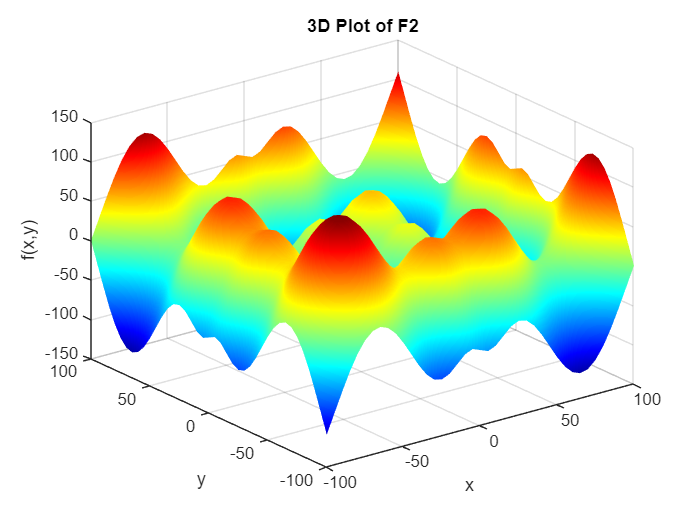

Algorithm: GA


  Avg Performance: -127.2700


  Std Deviation:   0.0000


  Best Performance: -127.2700


  Worst Performance: -127.2700


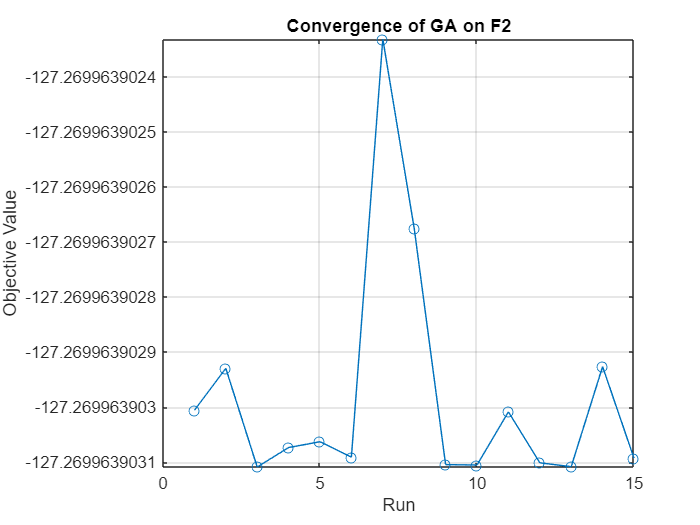

Algorithm: PSO


  Avg Performance: -124.8079


  Std Deviation:   5.4808


  Best Performance: -127.2700


  Worst Performance: -108.8042


Algorithm: SA


  Avg Performance: -106.3732


  Std Deviation:   17.1339


  Best Performance: -127.2670


  Worst Performance: -78.4797


Function: F10


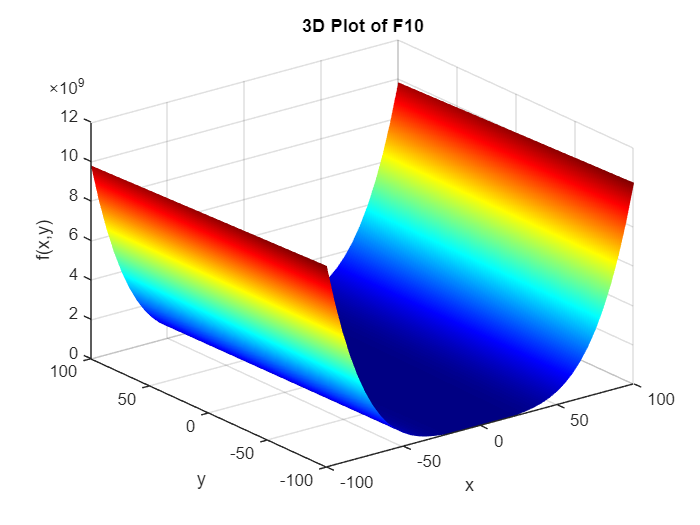

Algorithm: GA


  Avg Performance: 0.6975


  Std Deviation:   2.6491


  Best Performance: 0.0000


  Worst Performance: 10.2733


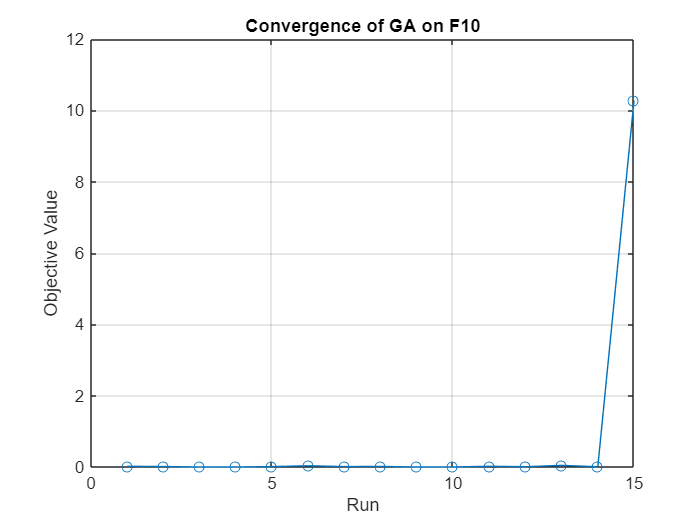

Algorithm: PSO


  Avg Performance: 3.8044


  Std Deviation:   11.3867


  Best Performance: 0.0000


  Worst Performance: 42.7468


Algorithm: SA


  Avg Performance: 0.2424


  Std Deviation:   0.3334


  Best Performance: 0.0056


  Worst Performance: 1.0000


Function: F16


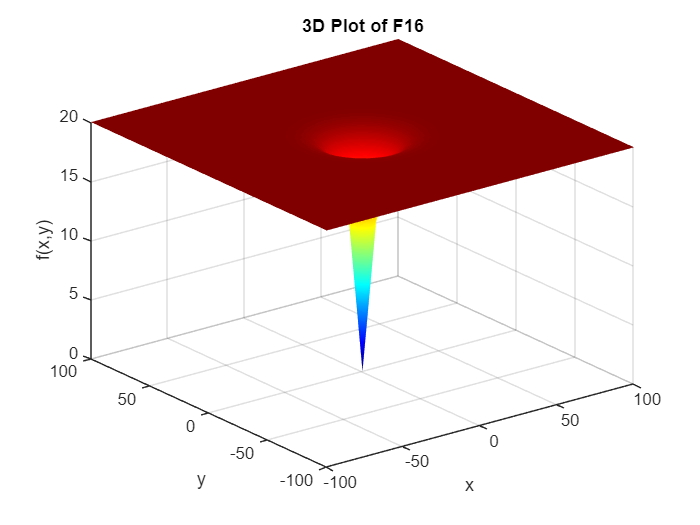

Algorithm: GA


  Avg Performance: 0.0000


  Std Deviation:   0.0000


  Best Performance: 0.0000


  Worst Performance: 0.0001


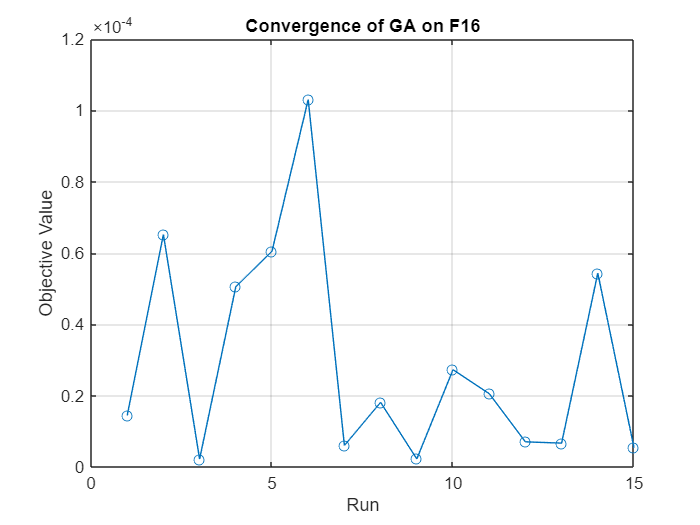

Algorithm: PSO


  Avg Performance: 2.6667


  Std Deviation:   7.0373


  Best Performance: 0.0000


  Worst Performance: 20.0000


Algorithm: SA


  Avg Performance: 0.0000


  Std Deviation:   0.0000


  Best Performance: 0.0000


  Worst Performance: 0.0000


--- Dimensions: 10 ---


Function: F2


Algorithm: GA


  Avg Performance: -598.9177


  Std Deviation:   32.8046


  Best Performance: -636.1444


  Worst Performance: -545.8515


Algorithm: PSO


  Avg Performance: -568.0263


  Std Deviation:   11.4680


  Best Performance: -590.1855


  Worst Performance: -553.2540


Algorithm: SA


  Avg Performance: -369.3292


  Std Deviation:   68.0505


  Best Performance: -502.1786


  Worst Performance: -264.2877


Function: F10


Algorithm: GA


  Avg Performance: 23.2672


  Std Deviation:   29.1230


  Best Performance: 0.6119


  Worst Performance: 82.3287


Algorithm: PSO


  Avg Performance: 476.5555


  Std Deviation:   990.8782


  Best Performance: 4.9425


  Worst Performance: 2939.6072


Algorithm: SA


  Avg Performance: 8.8847


  Std Deviation:   0.0713


  Best Performance: 8.7093


  Worst Performance: 8.9666


Function: F16


Algorithm: GA


  Avg Performance: 0.1745


  Std Deviation:   0.4106


  Best Performance: 0.0111


  Worst Performance: 1.6498


Algorithm: PSO


  Avg Performance: 20.0000


  Std Deviation:   0.0000


  Best Performance: 20.0000


  Worst Performance: 20.0000


Algorithm: SA


  Avg Performance: 0.0000


  Std Deviation:   0.0000


  Best Performance: 0.0000


  Worst Performance: 0.0000


% --- Main Script ---
clear; clc;

% Define dimensions
dimensions = [2, 10]; % Add D=100 if desired

% Number of runs for each optimization algorithm
numRuns = 15;

% Define functions from CEC'2005 suite
functions = {@F2, @F10, @F16};
functionNames = {'F2', 'F10', 'F16'};

% Define optimization algorithms
algorithms = {'GA', 'PSO', 'SA'};

% Genetic Algorithm options
gaOptions = optimoptions('ga', 'Display', 'off', 'PopulationSize', 50, 'MaxGenerations', 100);

% Particle Swarm Optimization options
psoOptions = optimoptions('particleswarm', 'Display', 'off', 'SwarmSize', 50, 'MaxIterations', 100);

% Simulated Annealing options
saOptions = optimoptions('simulannealbnd', 'Display', 'off', 'MaxIterations', 300);

% Loop over dimensions
for d = dimensions
    fprintf('--- Dimensions: %d ---\n', d);
    
    % Loop over functions
    for fIndex = 1:length(functions)
        func = functions{fIndex};
        funcName = functionNames{fIndex};
        fprintf('Function: %s\n', funcName);
        
        % Define search space bounds
        lb = -100 * ones(1, d); % Lower bound
        ub = 100 * ones(1, d);  % Upper bound

        % Ensure bounds are of type double
        lb = double(lb);
        ub = double(ub);

        % Plot the function in 3D (only for D=2)
        if d == 2
            figure;
            [x, y] = meshgrid(-100:5:100, -100:5:100);
            z = arrayfun(@(a, b) func([a, b]), x, y);
            surf(x, y, z);
            title(['3D Plot of ', funcName]);
            xlabel('x'); ylabel('y'); zlabel('f(x,y)');
            colormap jet; shading interp;
        end

        % Loop over algorithms
        for aIndex = 1:length(algorithms)
            algorithm = algorithms{aIndex};
            fprintf('Algorithm: %s\n', algorithm);
            
            results = zeros(1, numRuns);
            
            % Run optimization multiple times
            for run = 1:numRuns
                switch algorithm
                    case 'GA'
                        [~, fval] = ga(func, d, [], [], [], [], lb, ub, [], gaOptions);
                        results(run) = fval;
                    case 'PSO'
                        [~, fval] = particleswarm(func, d, lb, ub, psoOptions);
                        results(run) = fval;
                    case 'SA'
                        % Define a starting point within the bounds
                        x0 = (lb + ub) / 2; 
                        [~, fval] = simulannealbnd(func, x0, lb, ub, saOptions);
                        results(run) = fval;
                end
            end
            
            % Calculate statistics
            avgPerformance = mean(results);
            stdDeviation = std(results);
            bestPerformance = min(results);
            worstPerformance = max(results);
            
            % Display results
            fprintf('  Avg Performance: %.4f\n', avgPerformance);
            fprintf('  Std Deviation:   %.4f\n', stdDeviation);
            fprintf('  Best Performance: %.4f\n', bestPerformance);
            fprintf('  Worst Performance: %.4f\n', worstPerformance);

            % Plot convergence (only for D=2)
            if d == 2 && strcmp(algorithm, 'GA')
                figure;
                plot(1:numRuns, results, '-o');
                title(['Convergence of ', algorithm, ' on ', funcName]);
                xlabel('Run'); ylabel('Objective Value');
                grid on;
            end
        end
    end
end


% --- End of Main Script ---

% --- Benchmark Functions ---
function y = F2(x)
    % Shifted Schwefel’s Problem (Example Placeholder)
    y = sum(-x .* sin(sqrt(abs(x)))); % Replace with actual CEC'2005 definition
end

function y = F10(x)
    % Rotated Rosenbrock’s Function (Example Placeholder)
    y = sum(100 * (x(2:end) - x(1:end-1).^2).^2 + (x(1:end-1) - 1).^2); % Replace with actual CEC'2005 definition
end

function y = F16(x)
    % Rotated Ackley’s Function (Example Placeholder)
    a = 20; b = 0.2; c = 2 * pi;
    n = length(x);
    sum1 = sum(x.^2);
    sum2 = sum(cos(c * x));
    y = -a * exp(-b * sqrt(sum1 / n)) - exp(sum2 / n) + a + exp(1); % Replace with actual CEC'2005 definition
end

% --- End of Benchmark Functions ---
